clear;clc;

%% Load data
data=load('cartilage_sample_1_62x252_1s.mat');

data=data.data.ItemsData(1,1);
data=data{1,1};

%% Cropping the fingerprint range
fp=210:1:900;  %% pixel range(say)
data=squeeze(data(:,:,fp));

%% 2D image array
flat_data= reshape(data, [], size(data, 3));


%% Cosmic ray removal
window_size=5;
for i= 1:length(flat_data)
        spectrumm=flat_data(i,:);
        window_size = 5;
        flat_data(i,:) = medfilt1(spectrumm, window_size);
end

%% Background removal
bg_data=data(1:30,:,:);
background=mean(bg_data,1:2); %along dim1 and dim2
background=squeeze(background);
background=background';
bg=repmat(background,length(flat_data),1);
flat_data_bg=flat_data-bg;


%% K-means for background removal
% % Perform K-Means Clustering
% K = 2; 
% [idx, centers] = kmeans(flat_data, K);
% % Reshape the clustered data back to the original 3D shape
% flat_data1 = reshape(idx, size(flat_data, 1), size(flat_data, 2));
% 
% %bg cluster either 1 or2
% background_cluster = 1; % Adjust if necessary
% % Create a binary mask to identify background areas
% background_mask = idx == background_cluster;
% % Calculate the mean spectrum of the background
% background_spectrum = flat_data(background_mask, :);



%% Baseline correction or autoflourescence removal and smoothening followed by normalization
polynomial_fp_order=4;
sgolay_width=3;
for i= 1:length(flat_data_bg)
        spectrumm=flat_data(i,:);
        spec=spectrumm;
        
        initial = true;
        while initial || overshoot_count > 24
            initial = false;
    
            polynomial_coefficients = polyfit(1:length(spec), spec, polynomial_fp_order);
            polynomial_values = polyval(polynomial_coefficients, 1:length(spec));
            
            overshoot_indices = polynomial_values > spectrumm;
            polynomial_values(overshoot_indices) = spectrumm(overshoot_indices);
            overshoot_count = sum(overshoot_indices);
    
            spec = polynomial_values;
            
        end
        % base corrrected
        to_smooth= (spectrumm - spec);
        flat_data_bs(i, :)=to_smooth;
        %smoothened
        to_norm = sgolayfilt(to_smooth, 1, sgolay_width);
        flat_data_s(i, :)=to_smooth;
        %normalized by area
        flat_data_n(i, :) = to_norm/trapz(to_norm); 

     
    end


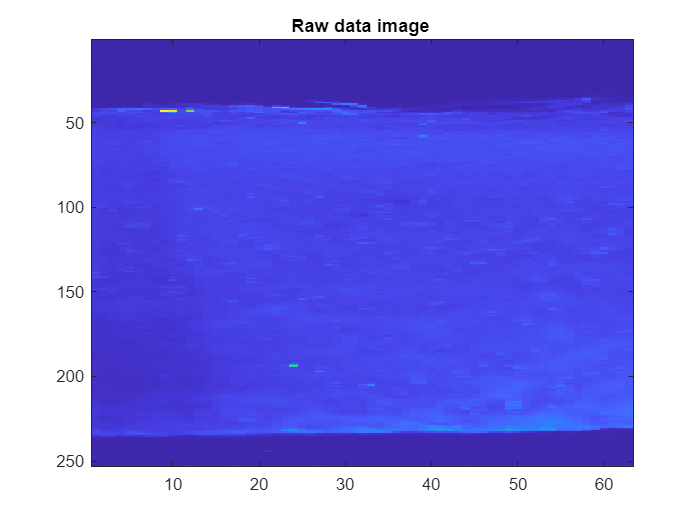



%% Get original data
data_bg= reshape(flat_data_bg, [size(data, 1), size(data, 2), size(data, 3)]);
data_bs= reshape(flat_data_bs, [size(data, 1), size(data, 2), size(data, 3)]);
data_s= reshape(flat_data_s, [size(data, 1), size(data, 2), size(data, 3)]);
data_n= reshape(flat_data_n, [size(data, 1), size(data, 2), size(data, 3)]);

%% Images upon processing
figure;
imagesc(data(:,:,500));
title('Raw data image ');

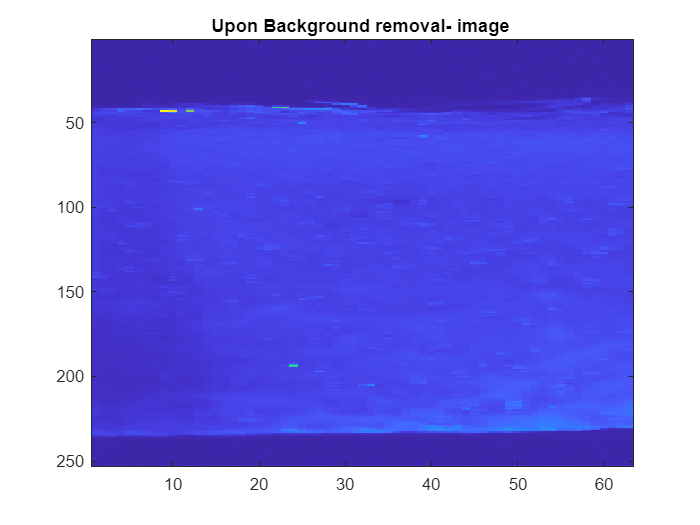

figure;
imagesc(data_bg(:,:,500));
title('Upon Background removal- image ');

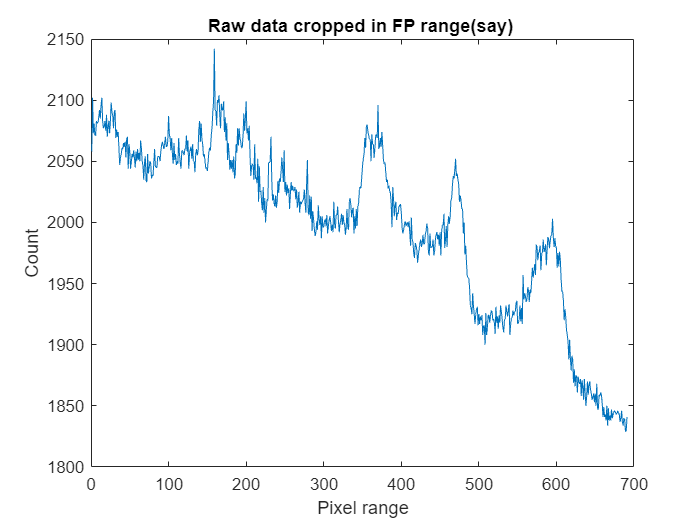


% figure;
% imagesc(data_bs(:,:,500));
% title('Upon baseline correction image ');
% figure;
% imagesc(data_s(:,:,500));
% title('Upon Smoothening-image ');
% 
% figure;
% imagesc(data_n(:,:,500));
% title('Upon Normalisation-image ');

%% Spectrums upon processing
figure();
plot(squeeze(data(100,32,:)));
title('Raw data cropped in FP range(say) ');
xlabel('Pixel range');
ylabel('Count');

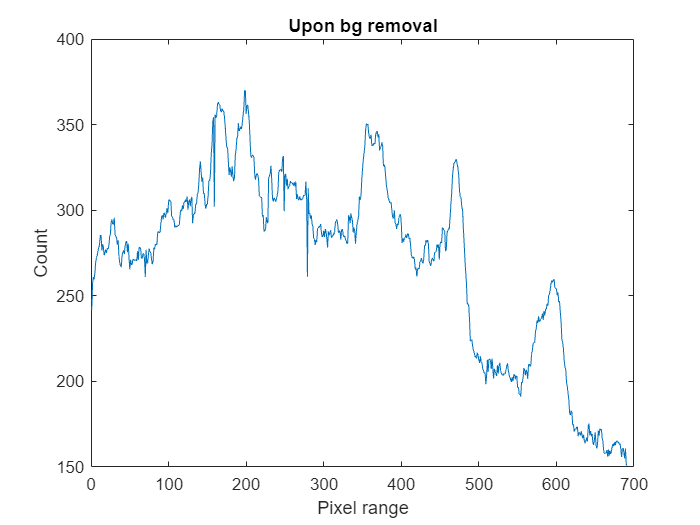


figure();
plot(squeeze(data_bg(100,32,:))); 
title('Upon bg removal');
xlabel('Pixel range');
ylabel('Count');

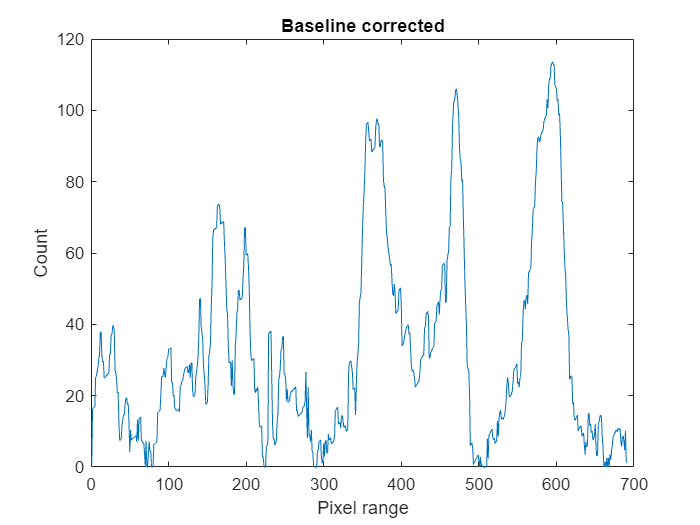


figure();
plot(squeeze(data_bs(100,32,:))); 
title('Baseline corrected');
xlabel('Pixel range');
ylabel('Count');

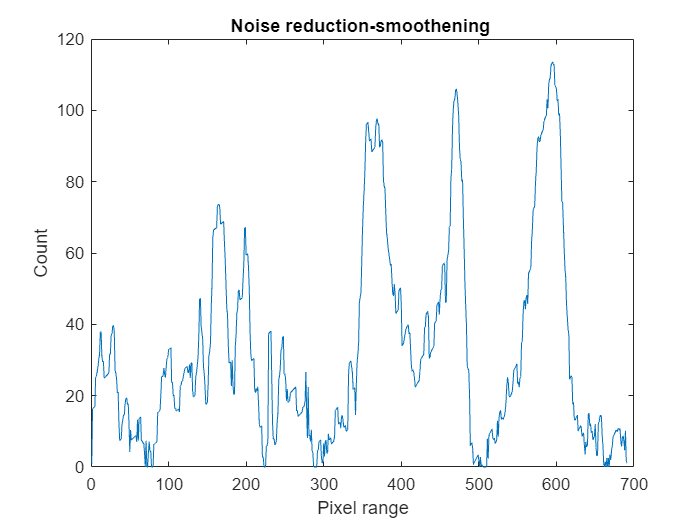


figure();
plot(squeeze(data_s(100,32,:))); 
title('Noise reduction-smoothening ');
xlabel('Pixel range');
ylabel('Count');

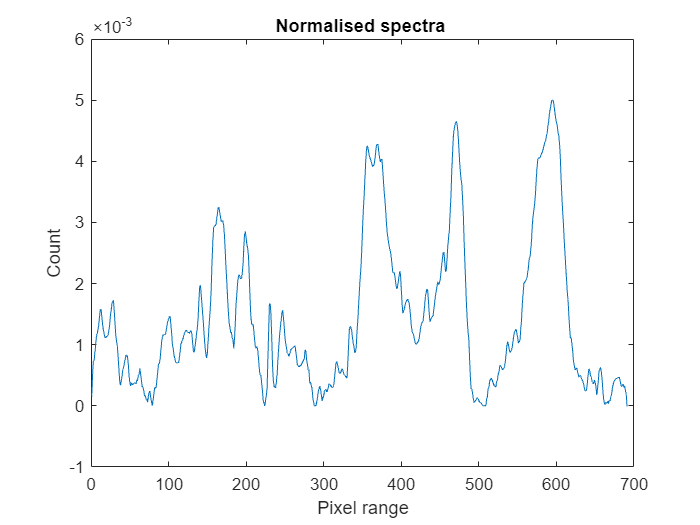


figure();
plot(squeeze(data_n(100,32,:)));
title('Normalised spectra ');
xlabel('Pixel range');
ylabel('Count');

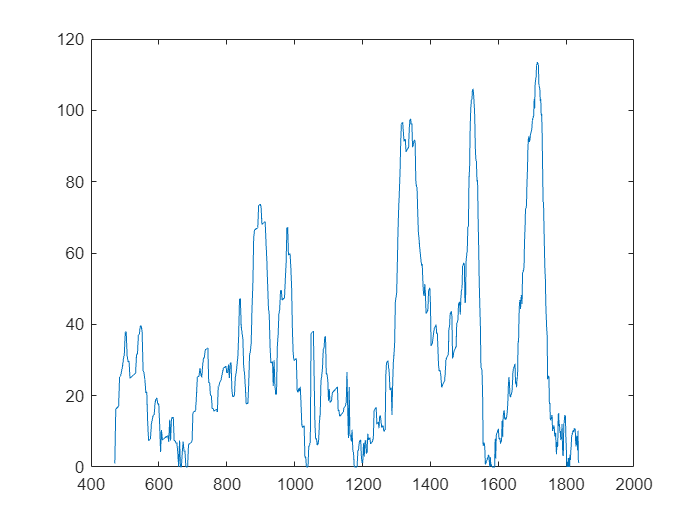

%calibrated axis
axiss=load("QePro_NIR_spectrum_axis.txt");
smooth=squeeze(data_s(100,32,:))';
figure;
plot(axiss(210:900),smooth);